# Analysis of Dipole Impedance

This example analyzes the impedance behavior of a center-fed dipole antenna for various mesh resolution/sizes at a single frequency of operation. The resistance and reactance of the dipole are compared with the theoretical results. A relative convergence curve is established for the impedance.

## Create Thin Dipole

Create a dipole antenna with a width of 1 cm.

mydipole = dipole(Width=1e-2);

## Calculate Baseline Impedance

Calculate the impedance and number of triangular facets in the default mesh. Since the dipole length is 2 m, choose the analysis frequency as half-wavelength frequency $f = c/(2*l)$, where c is the speed of light.

c = 2.99792458e8;
f = c/(2*mydipole.Length);
Zbaseline = impedance(mydipole,f);
meshdata  = mesh(mydipole);
Nbaseline = meshdata.NumTriangles;
Mbaseline = meshdata.MaxEdgeLength;

## Define Analysis Parameters

Create parameters to store the impedance, relative change in the impedance and mesh size.

Zin = Zbaseline;
numTri = Nbaseline;
Ztemp = Zin(1);

## Measure Impact of Mesh Accuracy on Antenna Impedance

The triangular surface mesh implies a discretization of the surface geometry into small planar triangles. All antenna surfaces in the Antenna Toolbox™ are discretized into triangles. You can evaluate the accuracy of the simulation results by uniformly refining the mesh. To specify the resolution of the mesh, provide the size of the maximum edge length, i.e. the longest side of a triangle among all triangles in the mesh, prior to analysis.

For each value of the maximum edge length, update the mesh, calculate the impedance at the predefined operating frequency, and calculate the number of triangles in the mesh. Store the impedance and the number of triangles in the mesh for subsequent analysis. Finally, calculate the relative change in the antenna impedance between subsequent mesh refinements until a desired convergence criterion is met. 

exptol = 0.002;
tolCheck = [];                
n = 1;
nmax = 12;
pretol = 1;
ShrinkFactor = 0.96;
while (n < nmax+1)&&(pretol > exptol)
    Mbaseline(n+1) = Mbaseline(n)*ShrinkFactor^(n-1);    
    meshdata = mesh(mydipole,MaxEdgeLength=Mbaseline(n+1));
    numTri(n+1) = meshdata.NumTriangles;   
    % Check if mesh has changed. Calculate impedance only if it has changed.
    if numTri(n+1)~=numTri(n)
        Zin(n+1) = impedance(mydipole,f);
        Zchange = abs((Zin(n+1)-Ztemp)/Zin(n+1));
    else
        Zin(n+1) = Zin(n);
        Zchange = pretol;
    end
    tolCheck(n) = Zchange;               
    pretol = tolCheck(n);
    Ztemp = Zin(n+1);
    n = n + 1;
end
tolValue = exptol.*ones(1,n);
tolCheck = [nan tolCheck];

## Plot Relative Convergence of Dipole Impedance

At the end of this analysis, the resistance $R_{in}$ $\approx 84\Omega$ and reactance $X_{in}$$\approx 45\Omega$. This value is in good agreement with the results reported in [1], [3]. Better results are obtained with an adaptive mesh refinement algorithm, which implies selective mesh refinement in the domain of a maximum numerical error. Plot the relative convergence curve of the dipole impedance with respect to the mesh size.

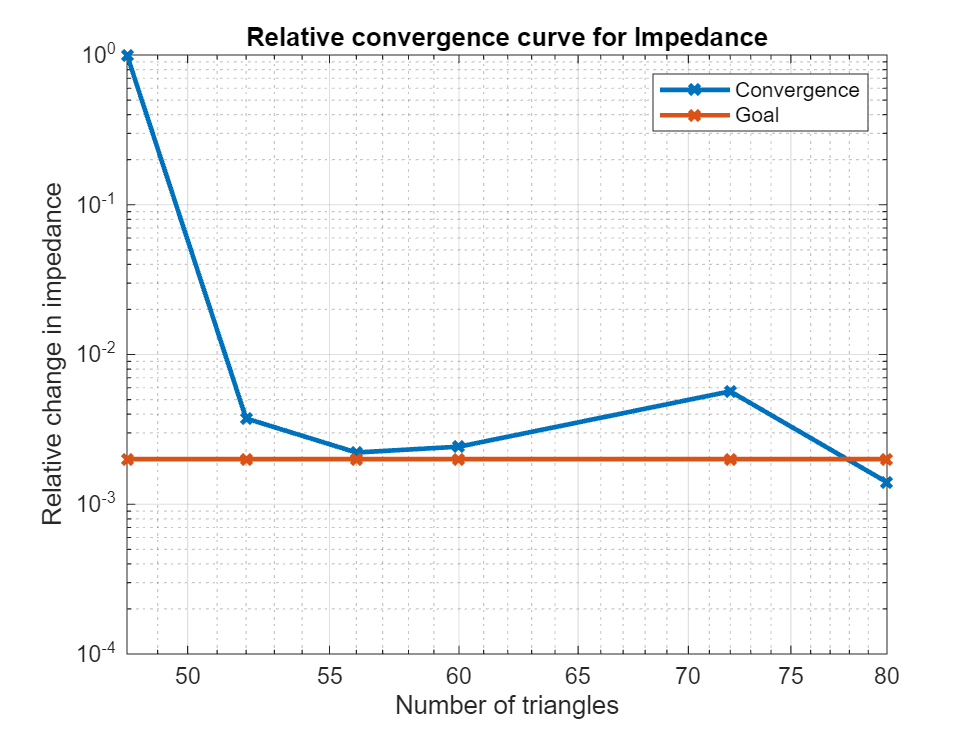

figure
loglog(numTri,tolCheck,'-x',LineWidth=2)
hold on
loglog(numTri,tolValue,'-x',LineWidth=2)
axis([min(numTri),max(numTri),10^-4,1])
grid on
xlabel("Number of triangles")
ylabel("Relative change in impedance")
legend("Convergence","Goal")
title("Relative convergence curve for Impedance")

## References

[1] Makarov, Sergey N. *Antenna and EM Modeling with Matlab*. New York: Wiley-Interscience, 2002.

[2] Balanis, Constantine A. *Antenna Theory: Analysis and Design*. Fourth edition. Hoboken, New Jersey: Wiley, 2016.

[3] Hansen, Robert C. “Carter Dipoles and Resonant Dipoles.” In *Proceedings of the Antenna Application Symposium*, pp.282–84. Allerton Park, Monticello, IL, 2010.

*Copyright 2014-23 The MathWorks, Inc.*